#     Hw-2 :::  

# Numerical Methods in Electromagnetics

Mohammadreza Arani                 1401/08/06                              810100511

clear; close all; clc;

## Problem:                                                          3.2

using CD (Central Difference):

${y^{\prime } }^{\prime } =\frac{y\left(i+1,j\right)-2y\left(i,j\right)+y\left(i-1,j\right)}{\left(h^2 \right)}\;\;;$ ==> $y\left(i+1,j\right)-2y\left(i,j\right)+y\left(i-1,j\right)-h^2 y\left(i,j\right)=-h^2$

    del_x = 0.25;
    L=1;  % Length of 1-D geometry
    x = 0:del_x:L;
    n = length(x);
    y = zeros(1,n)+1;
    % Boundary conditions:
    y(1,n) = 2 ;

from $y^{\prime } \left(0\right)=0-\to \;y\left(1,-1\right)=y\left(1,1\right)-\to \mathrm{Symmetry}\;$

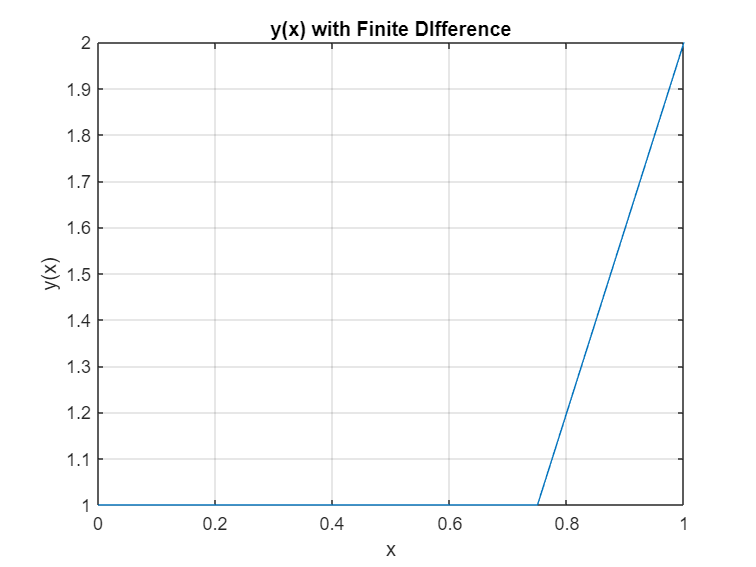

    % for:
    h  = del_x;
    % Finite DIfference Formula:
    for i = 1:length(y)-2
        if(i-1>0 )
             y(1,i+1) = (h^2+2)*y(1,i) -h^2 - y(1,i-1) ;
        else
             y(1,i+1) = (h^2+2)*y(1,i) -h^2 - y(1,1) ;
        end
    end


    % Illustrate the figure:
     figure()
     plot(x,y)
     title("y(x) with Finite DIfference")
     xlabel("x")
     ylabel("y(x)")
     grid on

### Or we can use more than 1 row and have a system of equations:

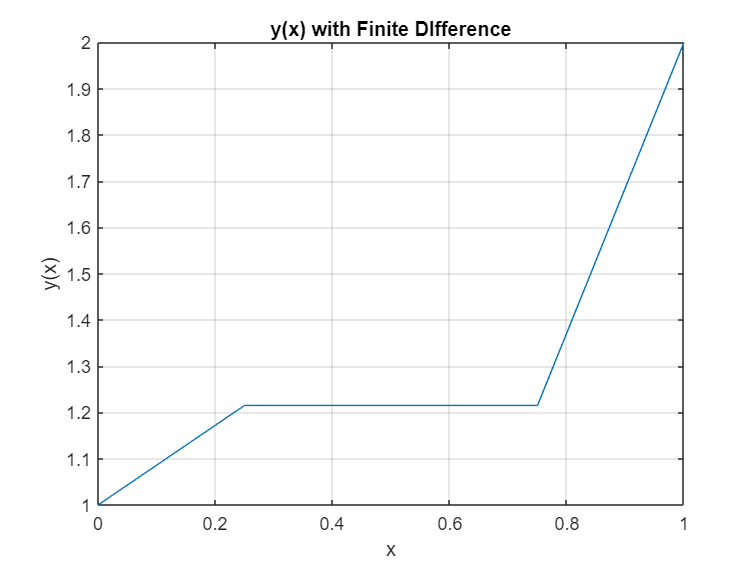

A = zeros(n-2);
B = zeros(1,n-2);

     for i=1:n-2
        A(i,i) = -(h^2+2) ;
     end
     for i=2:n-2
        A(i,i-1) = 1 ;
        A(i-1,i) = 1 ;
     end
    
     B(1,1)   = -h^2 - y(1,1) ;
     B(1,n-2) = -h^2 - y(1,n) ;
     for i=2:n-3
        B(1,i) = -(h^2) ;
     end
    BB = B';

    % Solve the system:
    YY  = mldivide(A,BB) ;
    y(2:end-1)  = YY(1,:) ;

      % Illustrate the figure:
     figure()
     plot(x,y)
     title("y(x) with Finite DIfference")
     xlabel("x")
     ylabel("y(x)")
     grid on

## Hand written solution:

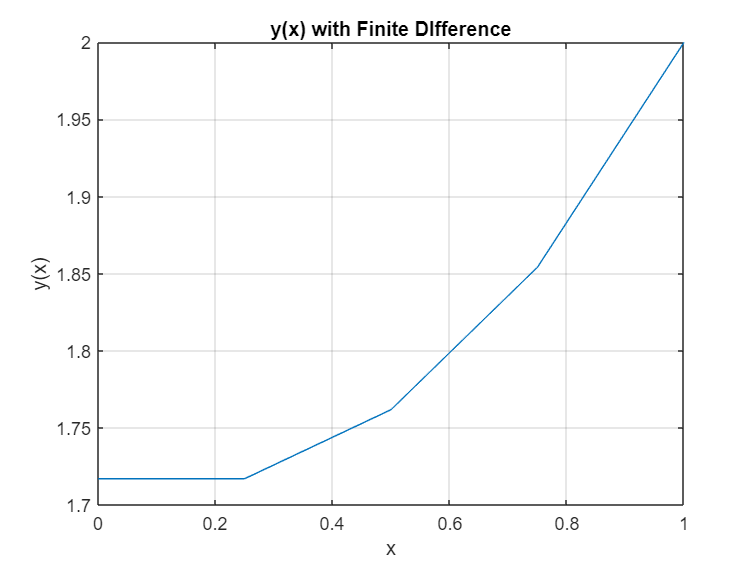

% The solution is in the paper:
     Afinal = [-17,16,0,0 ; 16,-33,16,0;  0,16,-33,16; 0,0,0,1 ];
     Bfinal = [-1;-1; -1;2] ;

    Yfinal  = mldivide(Afinal,Bfinal) ;
     % Illustrate the figure:
     figure()
     plot(x,[Yfinal(1);Yfinal])
     title("y(x) with Finite DIfference")
     xlabel("x")
     ylabel("y(x)")
     grid on

## MATLAB Solution:

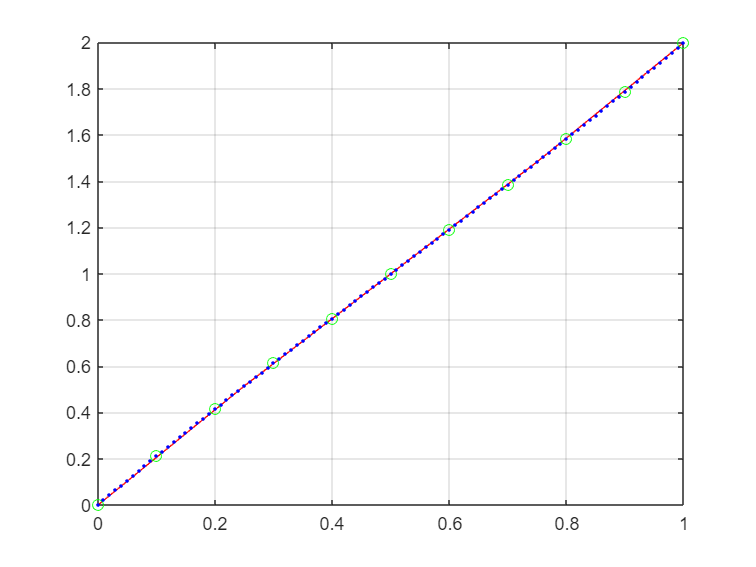


xlim = [0 1];
y0 = 0;
y1 = 2;
% 0:.25:1
[y5,x5] = mybvpsolve(xlim,y0,y1,5);

% 0:.1:1
[y11,x11] = mybvpsolve(xlim,y0,y1,11);
% 0:.01:1
[y101,x101] = mybvpsolve(xlim,y0,y1,101);
figure()
plot(x5,y5,'r-',x11,y11,'go',x101,y101,'b.')
grid on

function [y,x] = mybvpsolve(xlim,y0,y1,n)
  % y"+2y'+y=x^2
  % xlim is a vector of length 2
  % y0, y1 are the BC at each end
  % n is the number of elements in the final result
  
  x = linspace(xlim(1),xlim(2),n)';
  
  % stride
  h = x(2) - x(1);
  
  % discretize the ODE into a tridiagonal matrix
  % ((y(i+1)-2y(i)+y(i-1))/h^2) + 2*(y(i+1)-y(i-1)/2h + y(i)=x(i)^2;
  
  % ((y(i+1)-2y(i)+y(i-1))/h^2) - y(i)=-1;

  % so the main diagonal has coefficients
  % the 1 at each end brings the boundary conditions into the problem.
  maindiag = [1;repmat(-2/h^2 -1 ,n - 2,1);1];
  % be careful to create the sub and super diagonals as the correct lengths
  subdiag = [repmat(1/h^2 ,n-2,1);0];
  supdiag = [0;repmat(1/h^2 ,n-2,1)];
  
  % 3 calls to diag will do the trick here. For large problems, a
  % sparse matrix would be faster and better yet.
  ODEmat = diag(maindiag) + diag(subdiag,-1) + diag(supdiag,1);
  
  % create the right hand side for the solve:
  rhs = [y0;-1*ones(n-2,1);y1];
  
  % solve. This is just a call to backslash
  y =ODEmat\rhs;
  
end

